# 下浮率预测模型：BP

### 传递函数 TF

- `'purelin', 'tansig', 'logsig'`

- 一般隐含层传递函数选择 `tansig` 或者 `logsig`，输出层传递函数选择 `tansig` 或者 `purelin`

### 学习训练函数 BTF

- 一般选择 `'traingdx', 'trainrp', 'trainscg', 'trainoss', 'trainlm'`

#### 资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

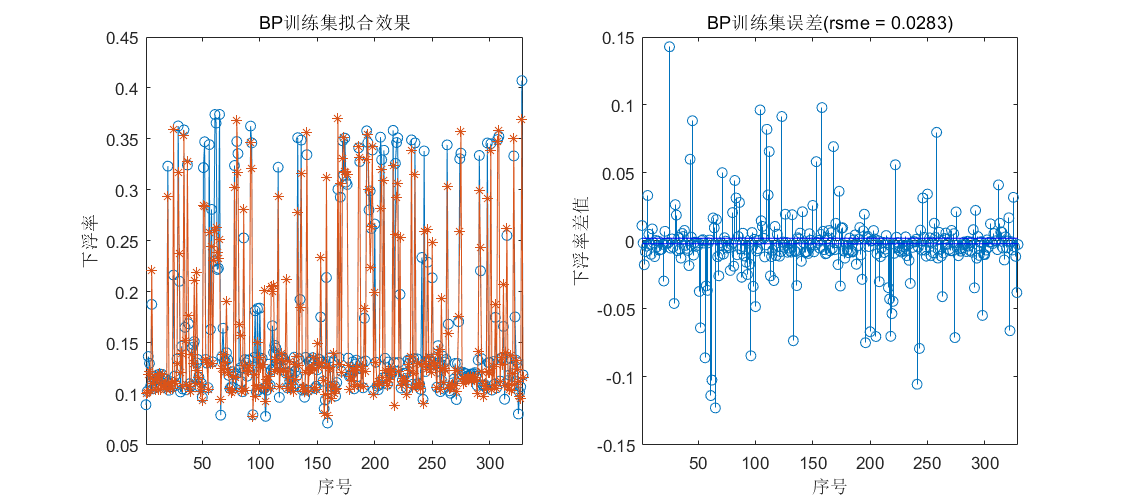

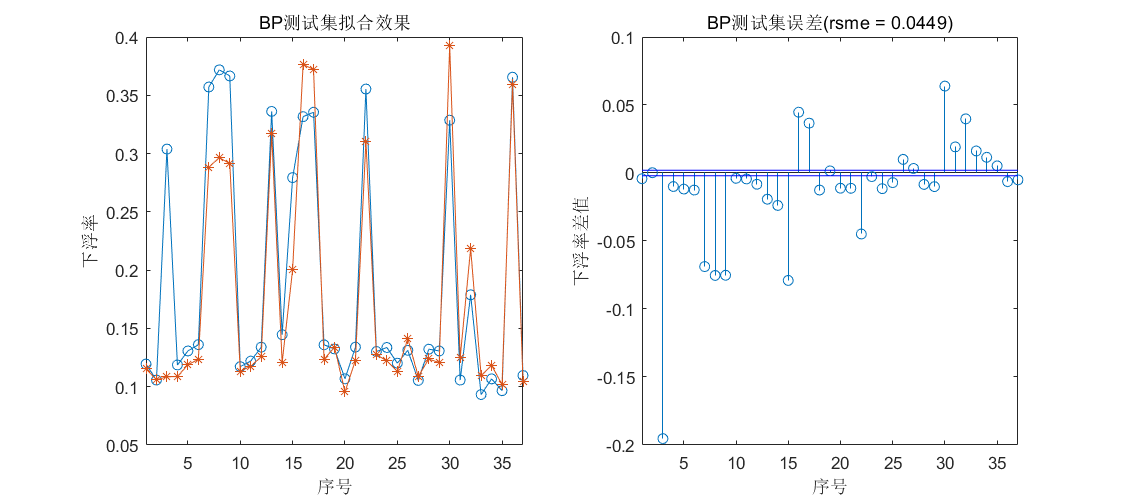

#### 资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期、投标人数、P值下浮率 → 投标人数、P值下浮率

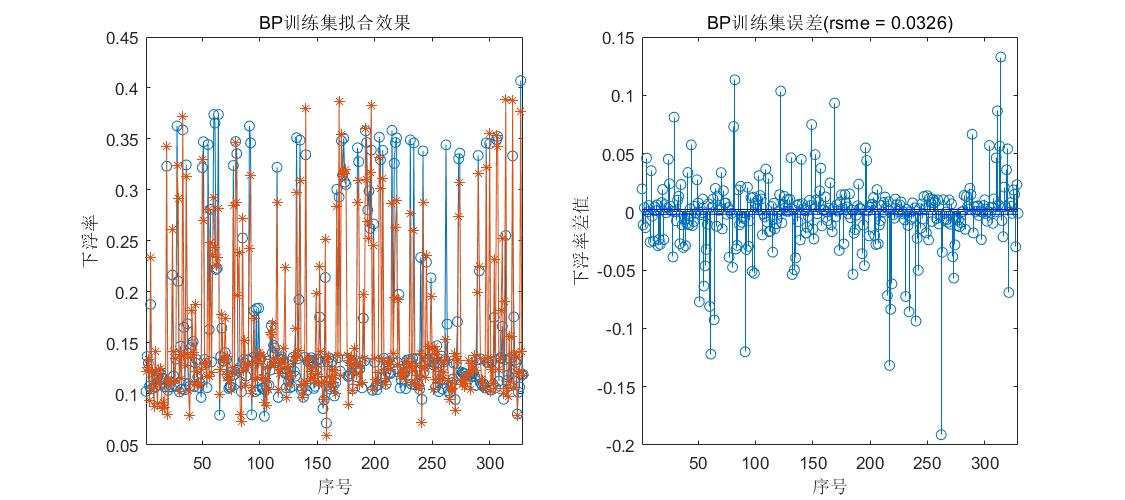

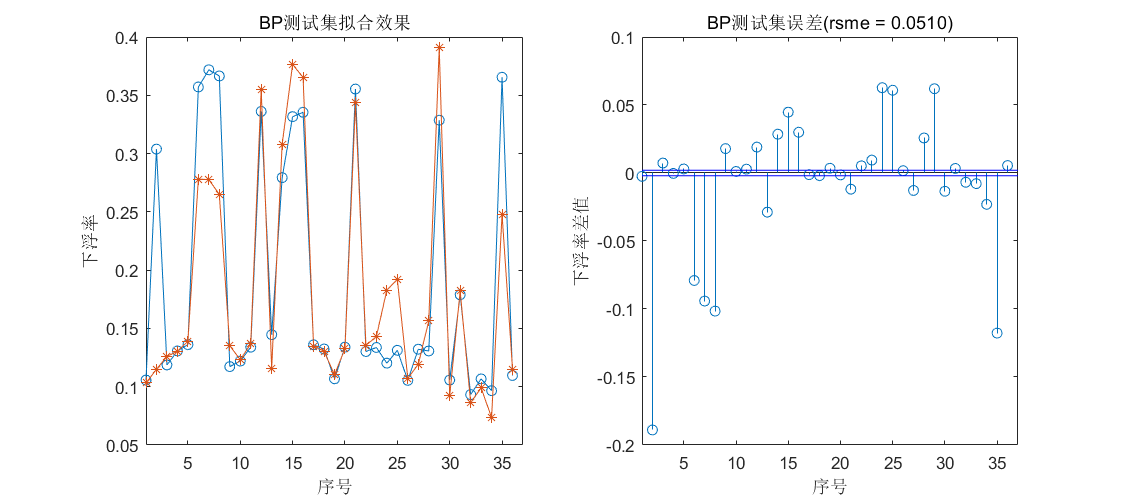

#### 选择下浮率小于 0.15 部分：资质要求、最高报价、下浮率、工资、开标时间、镇区、计划工期 → P值下浮率

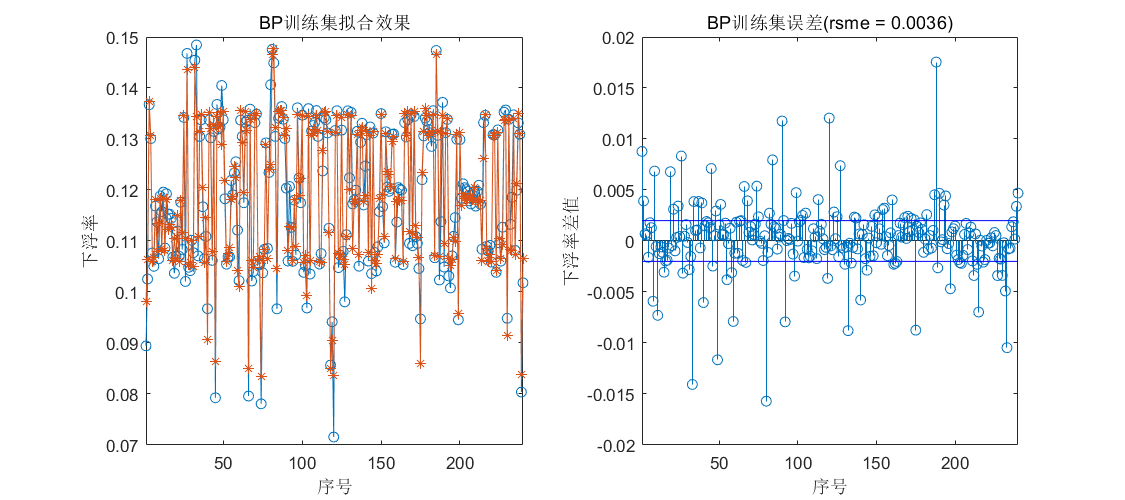

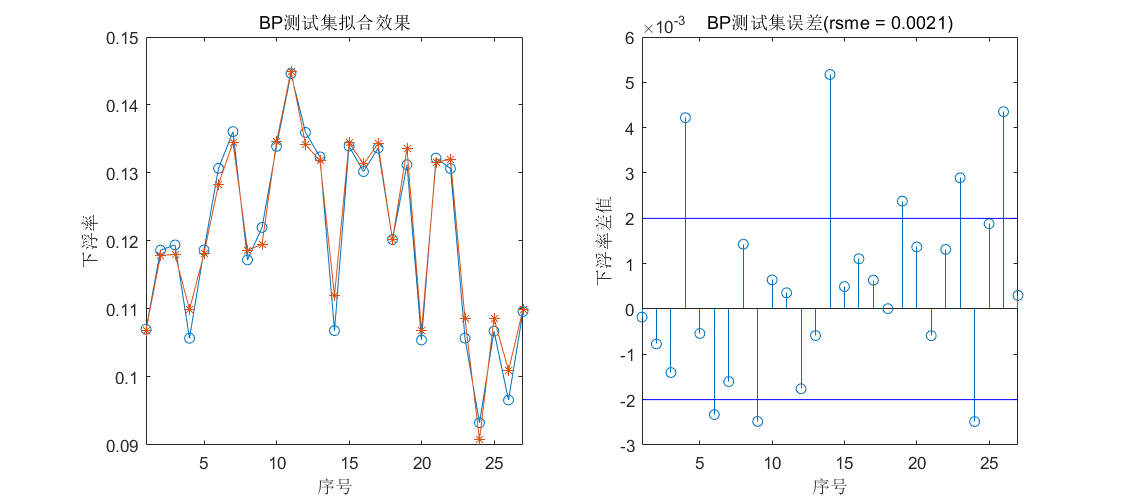

clear;clc;close all;
%%%%%%%%%%%%%%%%%%%%%%%%%% 加载数据
filename = '\\longde\longde\008-投标中心\006-数据分析中心\分析结果汇总\zb_ML.xlsx';
file = readtable(filename, 'Sheet', 1, 'VariableNamingRule', 'preserve');
data = table2array(file(:, 2:end));
% 数据筛选
indx = find(data(:, end) <= 0.15);
data = data(indx, :);
% 输入、输出数据提取
% 方式一：已知信息 → 未知信息
output = data(:, end);
input = data(:, 1:end-2);
% 方式二：已知信息 + 之前的结果信息 → 未知信息
% output = data(2 : end, end-1 : end);
% input = [data(2 : end, 1 : end-2), data(1 : end-1, end-1 : end)];
% 数据分成训练集（90%）和测试集（10%）
train_number = floor(0.9 * size(data, 1));
test_number = size(data, 1) - train_number;
input_train = input(1:train_number, :);
output_train = output(1:train_number, :);
input_test = input(train_number+1 : end, :);
output_test = output(train_number+1 : end, :);
% 归一化
[Yinput_train, PSinput_train] = mapminmax(input_train');
[Youtput_train, PSoutput_train] = mapminmax(output_train');
Yinput_test = mapminmax('apply', input_test', PSinput_train);
% 结果唯一
rng("default");
%%%%%%%%%%%%%%%%%%%%%%%%%% 初始化 BP 网络
net = newff(Yinput_train, Youtput_train, size(input, 2), {'tansig', 'purelin'});
net.trainFcn = 'trainlm';
net.trainParam.epochs = 1000;
net.trainParam.lr = 0.01;
net.trainParam.goal = 1e-5;
net.trainParam.showWindow = false;
% 训练
net = train(net, Yinput_train, Youtput_train);
%%%%%%%%%%%%%%%%%%%%%%%%%% 训练效果
output_train_pre = sim(net, Yinput_train);
% 反归一化
output_train_pre = mapminmax('reverse', output_train_pre, PSoutput_train);
output_train_pre = output_train_pre';
% 差值
err_train = output_train_pre(:, end) - output_train(:, end);
% 均方误差
rmse_train = rms(err_train);
line_up_train = 0.002 * ones(1, train_number);
line_down_train = -0.002 * ones(1, train_number);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(output_train(:, end), '-o');
xlabel('序号');
ylabel('下浮率');
title('BP训练集拟合效果');
hold on
plot(output_train_pre(:, end), '-*');
hold off
xlim([1, train_number]);
subplot(1, 2, 2);
stem(err_train);
xlabel('序号');
ylabel('下浮率差值');
title(sprintf('BP训练集误差(rsme = %.4f)', rmse_train));
hold on
plot(line_up_train, 'b');
plot(line_down_train, 'b');
hold off
xlim([1, train_number]);
%%%%%%%%%%%%%%%%%%%%%%%%%% 测试验证
output_test_pre = sim(net, Yinput_test);
% 反归一化
output_test_pre = mapminmax('reverse', output_test_pre, PSoutput_train);
output_test_pre = output_test_pre';
% 差值
err_test = output_test_pre(:, end) - output_test(:, end);
% 均方误差
rmse_test = rms(err_test);
line_up_test = 0.002 * ones(1, test_number);
line_down_test = -0.002 * ones(1, test_number);
% 画图
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1);
plot(output_test(:, end), '-o');
xlabel('序号');
ylabel('下浮率');
title('BP测试集拟合效果');
hold on
plot(output_test_pre(:, end), '-*');
hold off
xlim([1, test_number]);
subplot(1, 2, 2);
stem(err_test);
xlabel('序号');
ylabel('下浮率差值');
title('BP测试集误差');
title(sprintf('BP测试集误差(rsme = %.4f)', rmse_test));
hold on
plot(line_up_test, 'b');
plot(line_down_test, 'b');
hold off
xlim([1, test_number]);